# Example: Array Math and Vector Iteration

## Context

Newton's Law of cooling is a physical model that has proven to be useful to predict the dynamics of an object's temperature, $T$, as the object cools or warms toward and ambient temperature $T_{\text{env}}$.

The model is a first-order differential equation:

$\frac{dT}{dt}=-k \, (T-T_{\text{env}})$    (1)

where $k$ is the constant, positive cooling rate.

The solution to this ODE is

$T(t) = T_{\text{env}} + (T_0 - T_{\text{env}})\,e^{-kt}$      (2)

To make this example specific, let's image the following example:

- A strong HVAC system for a classroom would have a heating constant of $k = 0.10 \, \text{min}^{-1$

- The classroom starts at $T_0 =$10 $^o \text{C}$ and his heated to $T_{\text{env}} = 20 \, ^o \text{C$

Tenv = 20;
T0 = 10;
k = 0.1;

## Exercise: Incrementally evaluate solution

Evaluate the solution, $T(t)$, for a set of time values by iterating through each time value, solving the equation (2) and adding a point to a plot.

Create a vector of time values from 0 -- 60 minutes where each element is 0.1 min larger than the previous.

tt = 0:0.1:60

tt =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


Create a `for `loop that iterates through each element in the `tt `vector.  For each iteration, calculate the value of $T(t)$ and add the new value to a 2d plot of time vs temperature.

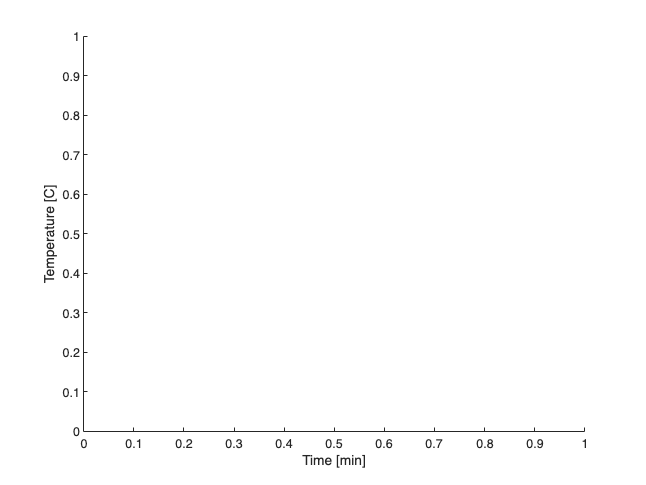

figure(1);
clf()
for ii = 1:length(tt)
    time = tt(ii);
    temp = 
    plot...


end
xlabel("Time [min]")
ylabel("Temperature [C]")

## Exercise: Array arithmetic to evaluate solution

Use Array Operations to operate element-wise over the entire time vector, $tt$, with a single line that yields a new vector, $TT$, that his the same size as $tt$ and stores the value for $T(t) $ for each element of the time vector


$$T(t) = T_{\text{env}} + (T_0 - T_{\text{env}})\,e^{-kt}$$
      

tt = linspace(0, 60, 1000);
TT = Tenv + (T0 - Tenv)*exp(-k*tt)

TT =    10.0000   10.0599   10.1194   10.1786   10.2374   10.2958   10.3539   10.4117   10.4691   10.5262   10.5829   10.6393   10.6954   10.7511   10.8065   10.8615   10.9162   10.9706   11.0247   11.0784   11.1319   11.1850   11.2377   11.2902   11.3424   11.3942   11.4457   11.4970   11.5479   11.5985   11.6488   11.6988   11.7485   11.7979   11.8470   11.8959   11.9444   11.9926   12.0406   12.0882   12.1356   12.1827   12.2295   12.2760   12.3223   12.3683   12.4140   12.4594   12.5045   12.5494


And then plot both time and temperature vectors with a single plot command

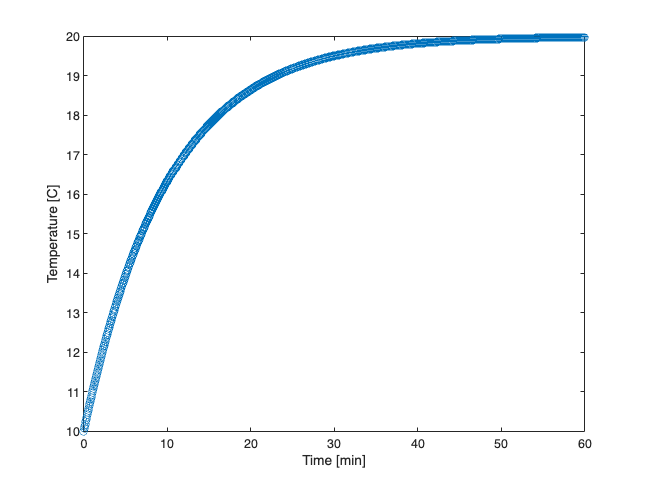

figure(2)
plot(tt,TT, 'o--')
xlabel("Time [min]")
ylabel("Temperature [C]")

## Exercise: Numerical approximation

So far, we have used the close-form solution provided in equation (2).   Another method is to approximate this solution with a difference equation.


$$T_{n+1} = T_n - k \,(T_n - T_{\text{env}})\,\Delta t$$



$$t_{n+1} = t_n + \Delta t$$


Start with our initial values for time and temperature

t = 0;
T = T0;

Create a `for `loop to iterate 600 times.  Each time recalculate values for `t` and `T` using $\Delta t = 0.1$min.

figure(3)
clf();
Dt = 0.1;
for ii = 1:600
    % Your code here
    
end
xlabel("Time [min]")
ylabel("Temperature [C]")